# Getting Started with the ELARA Toolbox

## Description

ELARA, short for **Efficient Lie-group Algorithms for Flexible Robotic Analysis and Control**, is a MATLAB toolbox for the simulation and optimal control of robotic (multibody) systems consisting of rigid and highly flexible links. It combines Lie-group kinematics on SE(3), rigid multibody dynamics, geometrically exact beam models, structure-preserving variational integration, and CasADi-based direct optimal control.

## Features

- Supports general rigid-flexible multibody models with open kinematics consisting of rigid links, flexible beam links, and screw joints (i.e., revolute, prismatic, or screw joints)

- Actuation via actuated screw joints or tendon actuation for continuum manipulators

- Time integration with highly efficient Lie-group variational integrator or any standard ODE solver via general interface (including all MATLAB ODE solvers)

- Fully CasADi-compatible implementation, e.g., for optimal control, parameter identification, or system optimization

- Direct optimal control with various time discretizations, including variational, Runge-Kutta (2nd and 4th order), and implicit-midpoint discretizations

- Extensive plotting, visualization, and animation functionality

- MEX generation (optional, but recommended) for increased performance

## Installation

To check if the installation was successful, you can run

elara.setup;

Verifying ELARA toolbox installation...
  [PASS]  Core toolbox installed correctly.
  [FAIL]  No compiled mex files found. Falling back to standard MATLAB functions.
  [PASS]  CasADi installation found.


To improve the performance of the simulations, you can use Matlab coder to build mex files. First ensure an appropriate compiler is configured using

% mex -setup C++

The mex files can then be build using

% elara.build;

After the mex files are compiled successfully, they will be automatically used by the toolbox.

For optimal control, install CasADi from *https://web.casadi.org/* and add it to the MATLAB path

## **Getting started**

The first step consists of defining the system. For this, two central classes, `MBLinkDefinitionRigid` and `MBLinkDefinitionFlexible`, can be used to specify the properties of all links in a system.

There are several example systems already implemented. Here, we will be using

links = systemDef_cantilever_system()

links = 1×3 heterogeneous MBLinkDefinition ( MBLinkDefinitionFlexible , MBLinkDefinitionRigid ) array with properties:
    parentLink
    isActuated
    jointAxis
    g_ref
    g_J_B
    d
    c
    M_a
    m_a
    g_a
    hasTCP
    g_B_TCP


The `systemDef_rigid_flexible_robot `function returns a link array, where each element is either of type `MBLinkDefinitionRigid `or `MBLinkDefinitionFlexible.`

To use these links in a simulation, you will need to generate a `MBSimulation `object by passing the links to the constructor:

simulation = MBSimulation(links, "displayInfo",false)

simulation =   MBSimulation with properties:

       Name: ""
     solver: [1×1 MBSimIntegratorVarIntBroyden]
      links: [3×1 MBLinkDefinition]
      MBSys: [1×1 MBSystemNum]
    simPars: [1×1 MBSimPars]
     simRes: [1×1 MBSimResults]


In this step, the individual links are assembled into a complete multibody system, which contains all information and properties of the system required for simulations or optimal control applications.

This multibody system is stored in the `MBSys` property of the `simulation `object`:`

system = simulation.MBSys

system =   MBSystemNum with properties:

              frameData: [1×1 MBSystemFrameDataNum]
                   cSys: [17×1 double]
                   dSys: [17×1 double]
                   qRef: [17×1 double]
           isCantilever: 1
                     g0: [4×4 double]
     AdjMatrixLinkGraph: [3×3 double]
    AdjMatrixFrameGraph: [7×7 double]
                 nLinks: 3
                nJoints: 2
                nFrames: 7
                   nDoF: 17
                nInputs: 2
       linkFrameIndices: [2×3 uint16]
          indexTCPFrame: 0
                g_B_TCP: [4×4 double]


RRef0 = [
    0  0 1
    0  1 0
    -1 0 0
    ];

% Properties of the system can also be changed afterwards, such as the
% orientation of the first link (which is fixed to the fixed base)
simulation.MBSys.g0 = SE3Matrix(RRef0, zeros(3,1));

The parameters of the simulation can be set using the `simulation.simPars` property:

% End time
simulation.simPars.tEnd = 5;

% Initial configuration
q0 = simulation.MBSys.setJointAngles(deg2rad([-30,90]));
simulation.simPars.q0 = q0;

simulation.simPars.qDot0 = zeros(simulation.MBSys.nDoF,1);

The type and parameters of the solver can be set using the `simulation.solver` property:

% Solver settings
simulation.solver = MBSimIntegratorVarIntBroyden;
simulation.solver.h = 2^-10;                        % h is always the variable for the step-size in this framework.
simulation.solver.JacobianIterationThreshold = 5;   
simulation.solver.errorMargin = 1e-11;
simulation.solver.aTrapez = 0;

If all parameters are set you can then start the simulation:

simulation = simulation.simulateSystem

Starting integration (varint-broyden)...
   Total integration time (tictoc):     6.802397 s
   Simulation end time:                 5.000 s
   Nr. of successful time steps:        5121
   Time step:                           9.766e-04 s = 2^-10.00 s
   Approx. comp. time per step:         1.328e-03 s
   Iteration Count (Avg/Min/Max/Total): 4.5863 / 2 / 8 / 23482
   Residual (Avg/Min/Max):              2.477e-12 / 2.309e-15 / 9.993e-12
   Target solver error violations:      0 (0.00% of overall steps)


simulation =   MBSimulation with properties:

       Name: ""
     solver: [1×1 MBSimIntegratorVarIntBroyden]
      links: [3×1 MBLinkDefinition]
      MBSys: [1×1 MBSystemNum]
    simPars: [1×1 MBSimPars]
     simRes: [1×1 MBSimResults]


The numerical results of the simulation are then available at

simulation.simRes

ans =   MBSimResults with properties:

                 eta: [6×7×5121 double]
                   g: [4×4×7×5121 double]
                   q: [17×5121 double]
               q_dot: [17×5121 double]
                tout: [5121×1 double]
    solverIterations: [8 2 3 3 3 3 3 3 3 3 4 4 4 3 4 4 4 4 4 4 4 4 3 3 3 3 3 3 3 3 3 3 3 3 3 3 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 5 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 5 5 5 5 5 5 5 5 6 3 4 4 4 4 4 4 4 4 4 4 4 4 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×5121 double)
         solverError: [1.9105e-12 9.0883e-13 1.1014e-13 2.9724e-14 4.6222e-13 2.4234e-13 9.1022e-13 2.6501e-12 1.3218e-12 5.2865e-12 1.4532e-13 3.4374e-14 5.1718e-14 2.0926e-12 6.7589e-14 1.7342e-13 2.4654e-13 2.5728e-13 5.9568e-13 … ] (1×5121 double)
      solverExitFlag: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

You can animate the completed simulation by running

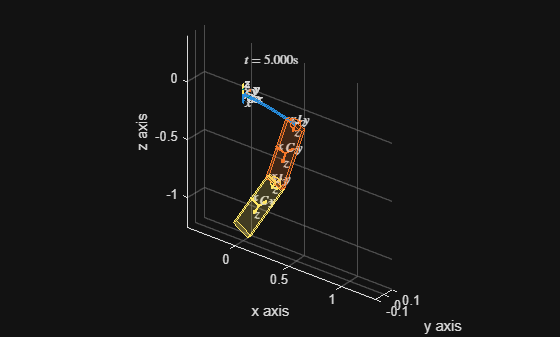

simulation.animateSimResults("figureName", "Animation Getting Started Guide");

If you want a lot of plots you can run

% simulation.plotAll

## Examples

There are several examples that have been implemented. These include

% simulation_continuum_manipulator
% simulation_rigid_flexible_system
% simulation_rigid_robot
% simulation_rigid_flexible_robot_PD_control

Many of these demonstrate the numerical advantages gained by using the Lie-group variational integrator.